# Energy Management

Copyright © 2022, The MathWorks, Inc.

#### Prepared by,

Graham Dudgeon, MEng, PhD

Principal Technologist - Electrical Systems

MathWorks

## Overview

In this session, we are going to consider various supervisory control modes for microgrid operation. These modes are,

- **Grid Synchronization**, where we match the magnitude, frequency and phase of microgrid voltage to the utility voltage before closing the circuit breaker. If we do not match the voltages to within a certain tolerance, various unpleasant behaviors occur.

- **Grid Forming**, where certain generation units are under voltage and frequency control on an AC system, and voltage control on a DC system. An electrical system is incapable of operating in a secure and stable manner if grid forming control is not present.

- **Grid Following**, where certain generation units are under active and reactive power control on an AC system, and power control on a DC system. Grid following units do not directly contribute to voltage and frequency control, and instead 'follow' the voltage and frequency conditions at their terminals.

- **Curtailment**, where we reduce generation and/or load power. The main reason we curtail generation and/or load is to maintain security and stability when unplanned events occur or when operational conditions are stressing the grid.

- **AC/DC Power Flow**, where we control the flow of power from the DC side of a system to the AC side.

Other terms that are commonly used in microgrid operation include,

- **Islanded operation**, where the microgrid is disconnected from a utility grid. In this case, the microgrid load is served only from the microgrid generation units and the microgrid generation units must include grid-forming control.

- **Grid-connected operation**, where the microgrid is connected to a utility grid. In this case, the utility grid can supplement either the supply of power to the microgrid, or the microgrid can supply power to the utility grid. The utility grid is grid forming, and the micorgid generation units can operate in grid following mode.

The model we are using in this session uses Simscape components within Simscape Electrical. For an excellent example of a microgrid with various control modes that is implemented by Hydro-Québec using Specialized Power Systems, please refer to this entry on File Exchange - [Microgrid Dynamic Operation](https://www.mathworks.com/matlabcentral/fileexchange/93235-microgrid-dynamic-operation).

## The System

Run this code by clicking **Run Section** on the tab above,

load initData
open_system("Microgrid_with_Utility_Connection.slx")

The system is pre-constructed for convenience and our focus will be on the operation of the overall system. The system has a utility grid connection and energy management fuctions as described in the overview.

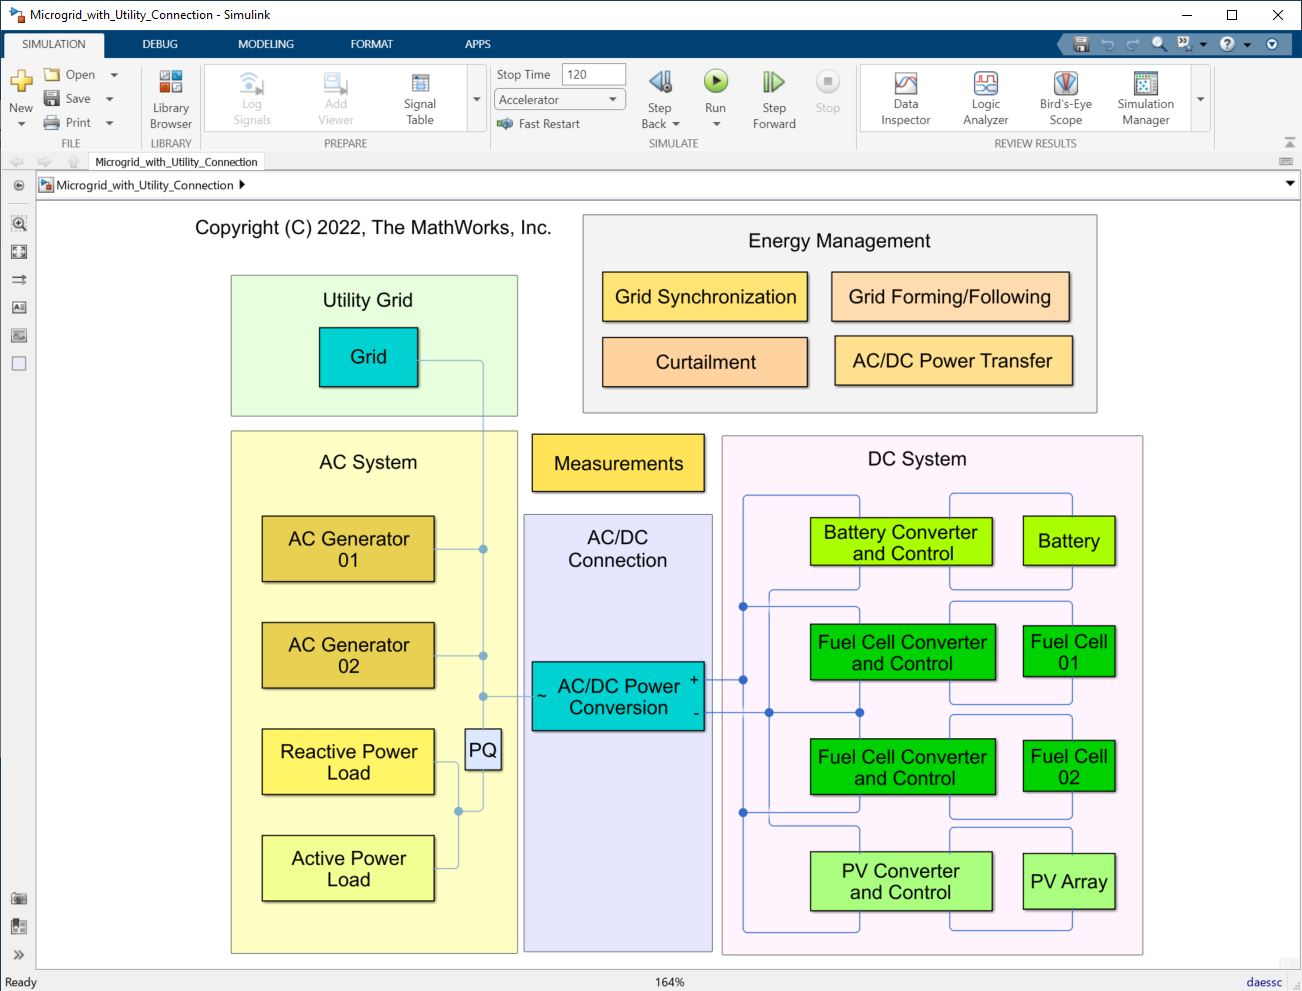

## Grid Synchronization

A grid-synchronization control system ensures that two or more electrical grids that are initially isolated have equal voltage magnitude, frequency and phase at the point-of-common-coupling (PCC) before the grids are connected.

If voltage magnitude, frequency and phase are not synchronized, then a large current can flow through the connection point which can damage equipment and compromise safety and security.

In our example we assume that the voltage magnitudes of the utility grid and microgrid are already within tolerance, and we will focus our attention on equalizing grid frequency and phase. 

Double-click on the Utility Grid subsystem to see the architecture at the point of common coupling PCC. You can see that we have represented the utility grid as an ideal three-phase voltage source with fixed voltage magnitude and frequency. We make various measurements at either side of the PCC.

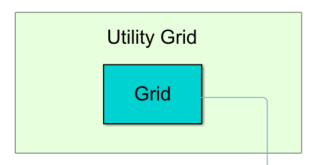

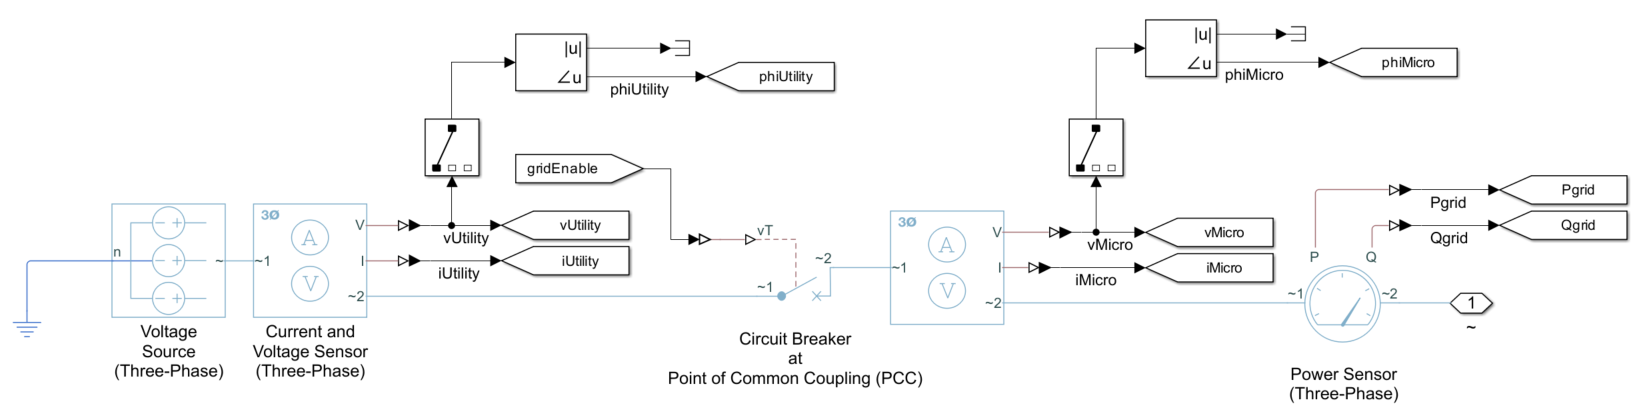

### Grid Synchronization Sequence

The grid synchronization sequence that we are following in our example is as follows,

- Bring frequency of microgrid to within some tolerance of the utility grid frequency by adjusting the frequency setpoints on the AC generators,

- Once the frequencies are within tolerance, wait until the phase angles of the utility grid and the microgrid are within some tolerance (simply waiting for phase angles to come within tolerance requires the frequencies to have some offset, the frequencies cannot be precisely equal)

- When the phase angles are within some tolerance, close the breaker at the PCC.

Double-click on the Grid Synchronization subsystem. You will see that there is a MATLAB Function block. with various inputs and outputs.

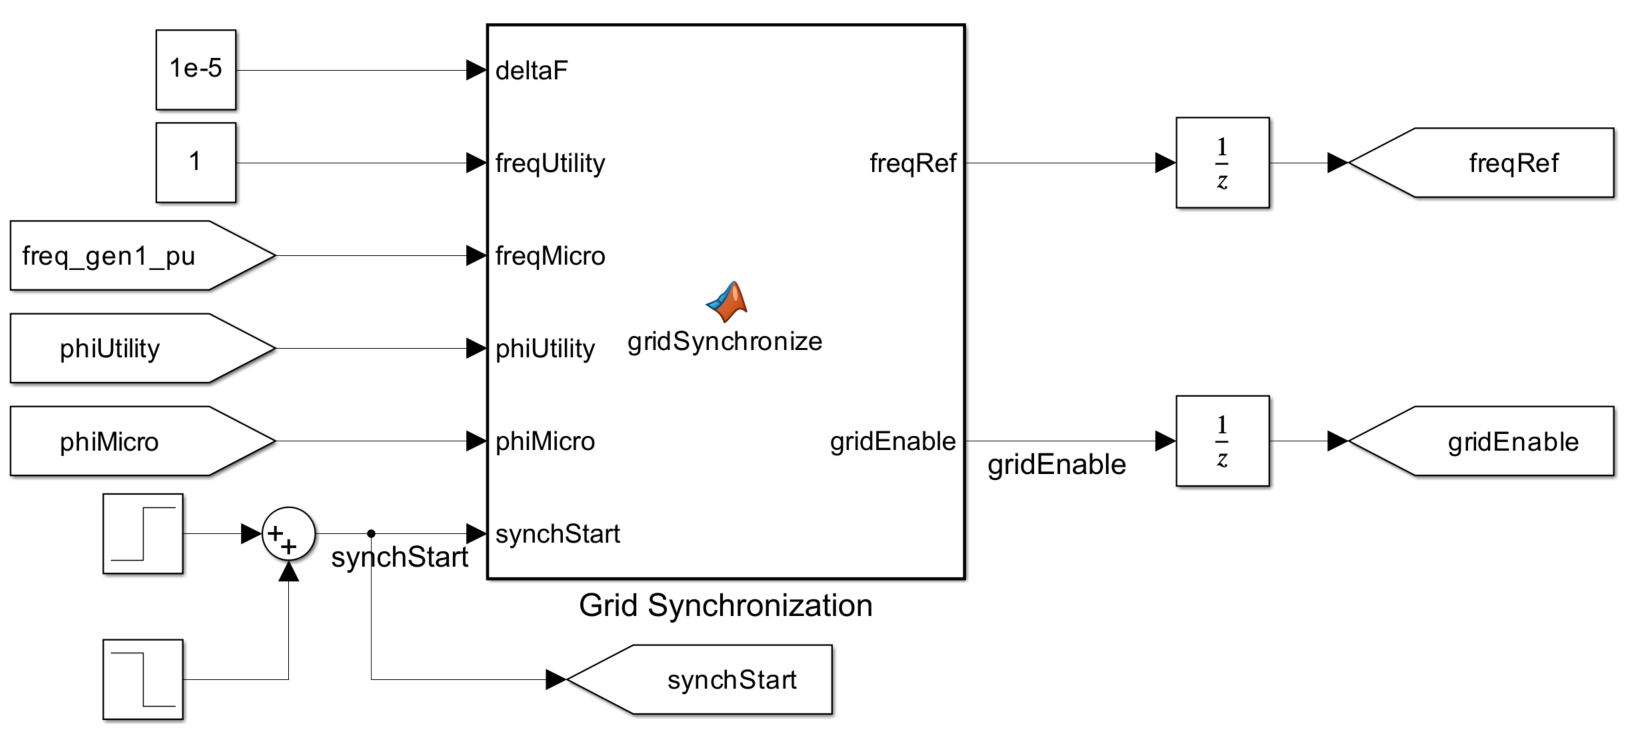

#### Inputs

deltaF - The size of step in per-unit (pu) that is taken to adjust the frequency reference.

freqUtility - The frequency of the utility grid in pu. In this case, our utility grid is an ideal voltage source that has a fixed frequency of 1 pu.

freqMicro - The frequency of the microgrid in pu. In this case we make our measurement from AC generator 1.

phiUtility - The phase angle of the utility grid frequency. In this case we measure phase A angle.

phiMicro - The phase angle of the microgrid frequency. In this case we measure phase A angle.

synchStart - a signal that when set to 1, instructs the grid synchronization algorithm to begin the synchronization process. When set to 0, the microgrid is islanded from the utility grid.

#### Outputs

freqRef - The frequency reference in per unit that is sent to the AC generators.

gridEnable - a signal that is sent to the circuit breaker at the point-of-common-coupling (PCC). When set to 0, the circuit breaker is closed. When set to 1, the circuit breaker is open.

Take a look at the MATLAB code and you will see the grid synchronization sequence described above.

Run the model. The grid is initally in islanded mode and a synchronization signal is enabled at 27 seconds. Observe generator 1 frequency and the frequency reference. Notice that the microgrid frequency is at 0.96pu due to frequency droop, and when the synchronization command is sent, the frequency reference is increased to 1.04 in order to bring the microgrid frequency to 1 pu.

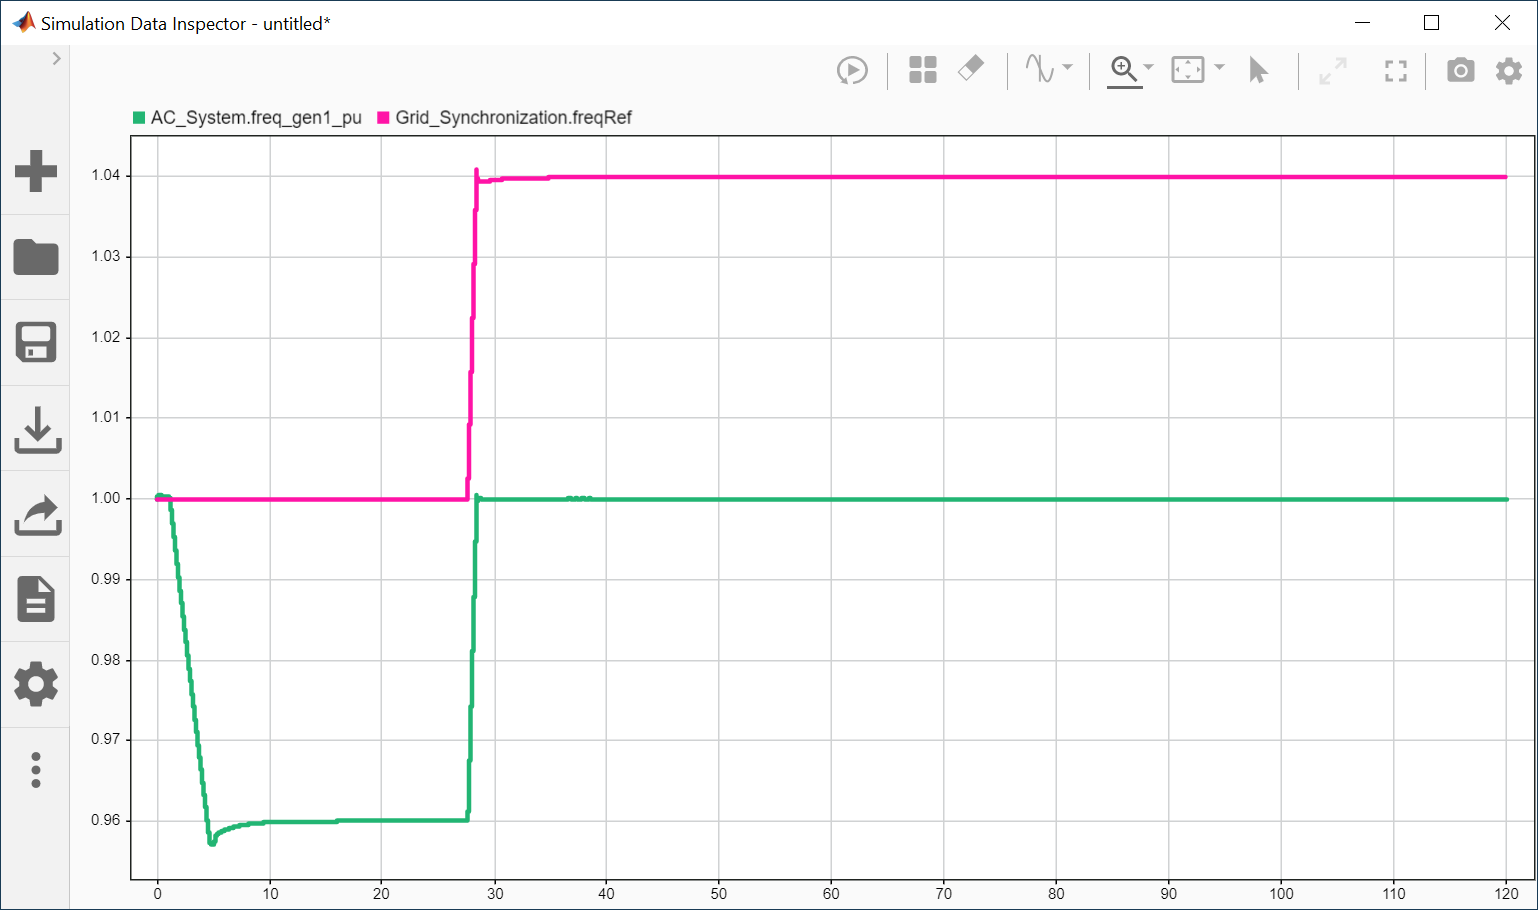

Once the frequencies are within tolerance, we then wait for the phase angles to come within tolerance.  The figure below shows phase A voltage for the utility grid and the microgrid at 30 seconds, when the frequencies are within tolerance. Notice that that the phase angles are not within tolerance at this stage. 

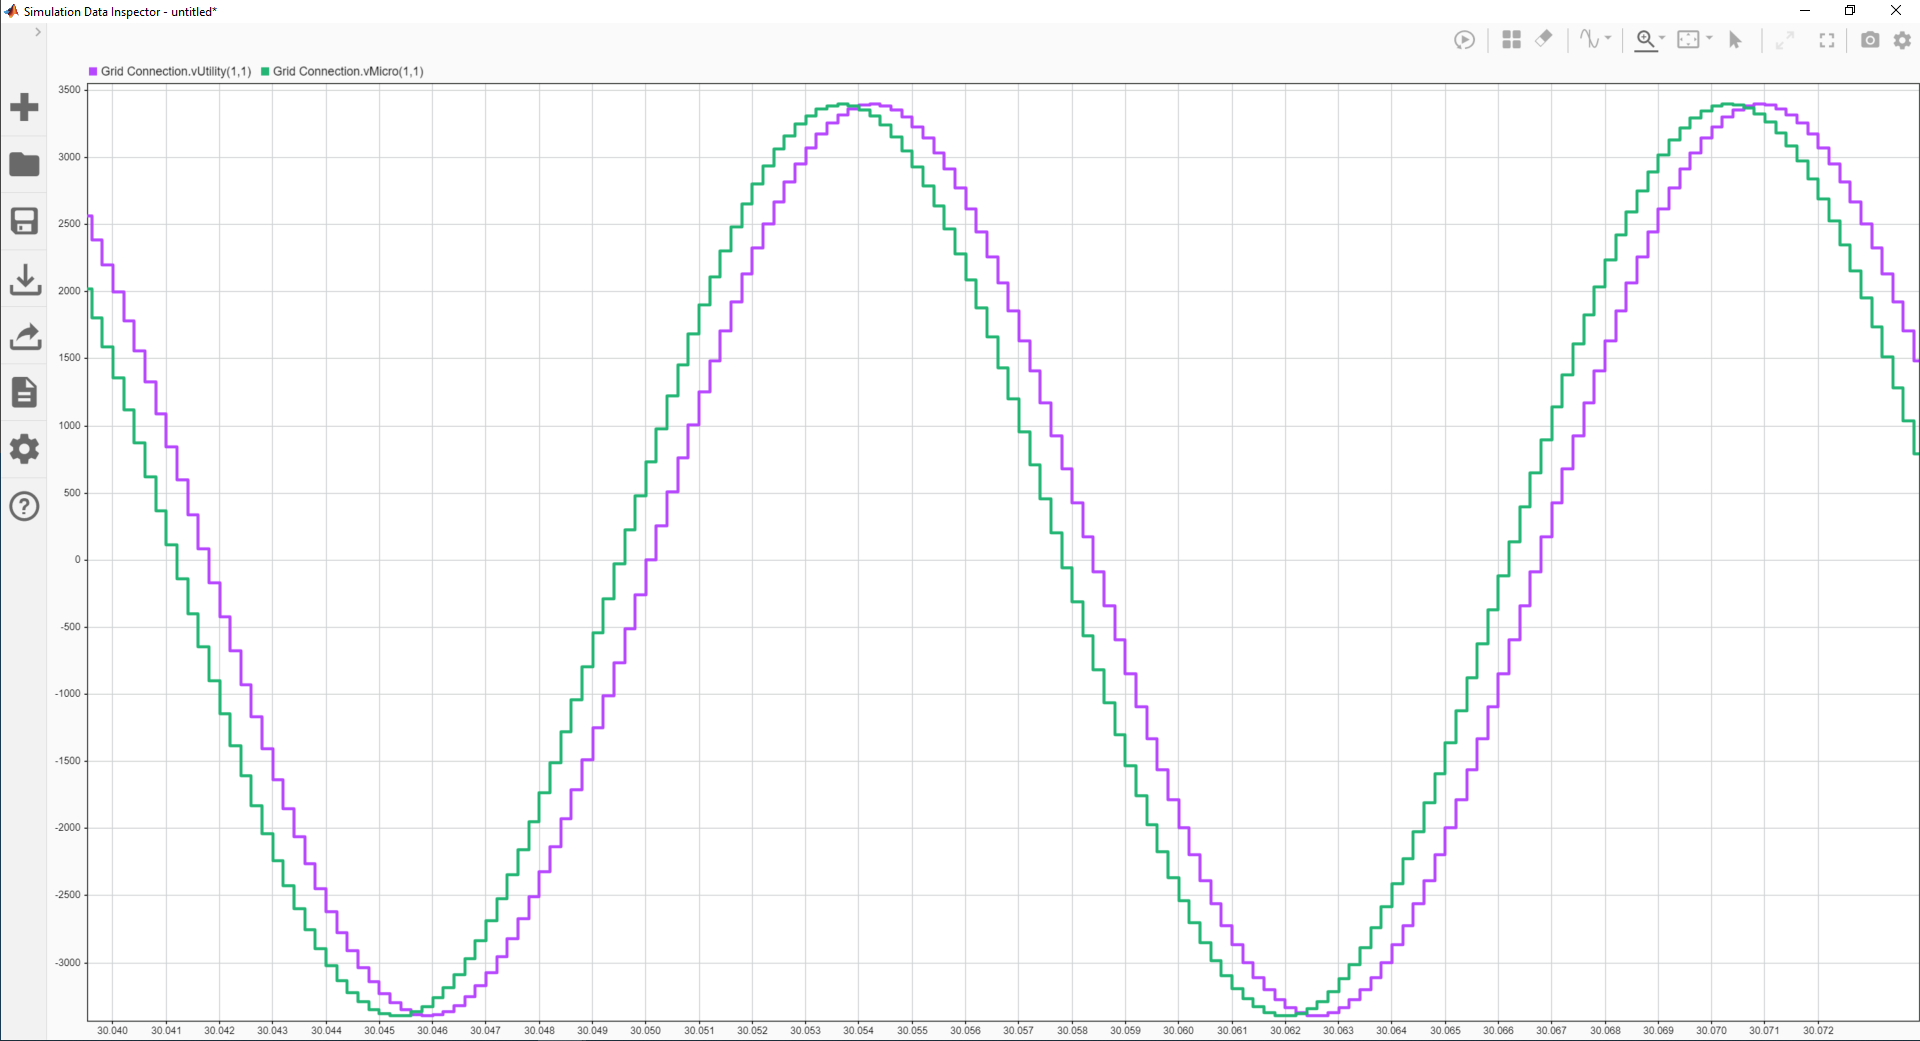

Because the frequencies are slightly different, we just need to wait until the phases overlap. This happens at around 36.38 seconds. You can see from the figure below that the phases are overlapped quite well prior to synchronization occuring.

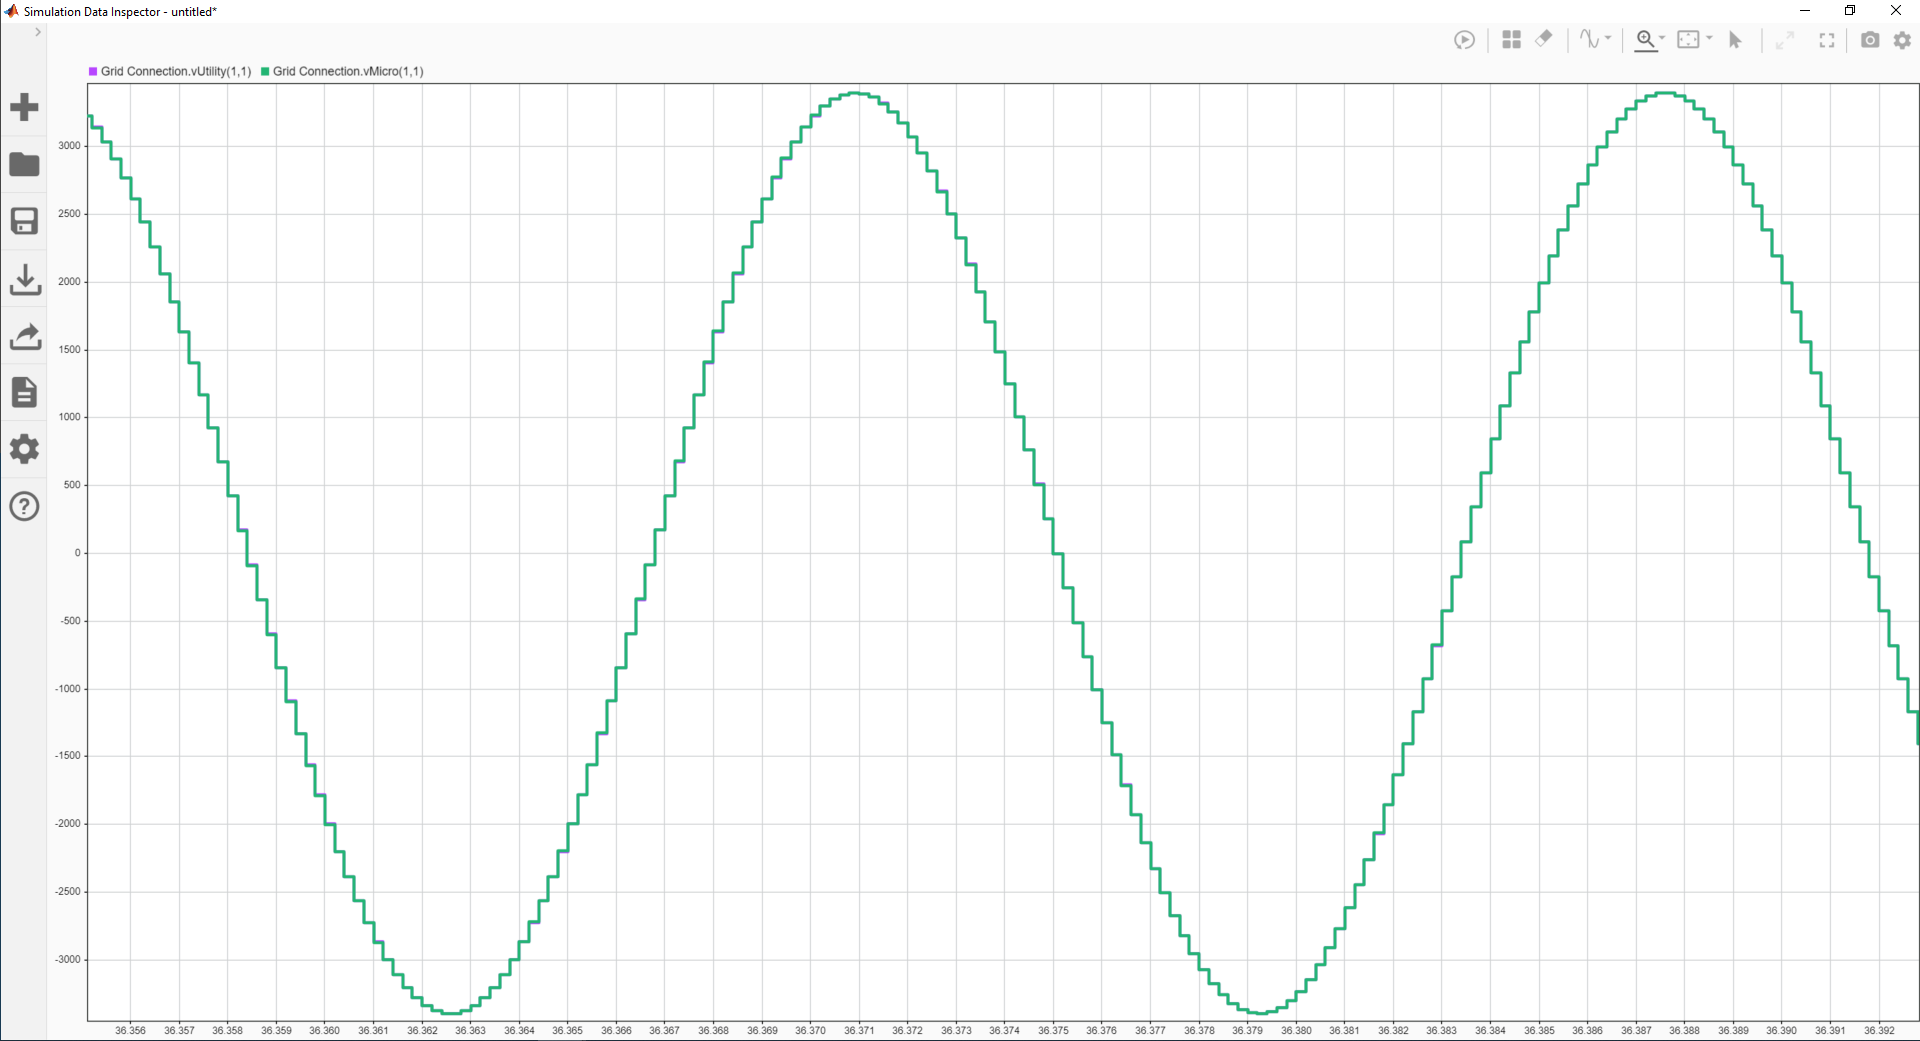

The figure below shows the current flowing through the point-of-common-coupling (PCC) - GridConnection.iUtility. Note that the peak current is around 17A. You may be wondering whether a peak of 17A is the result of an effective synchronization. To help answer that we'll look at an unsynchronized connection.

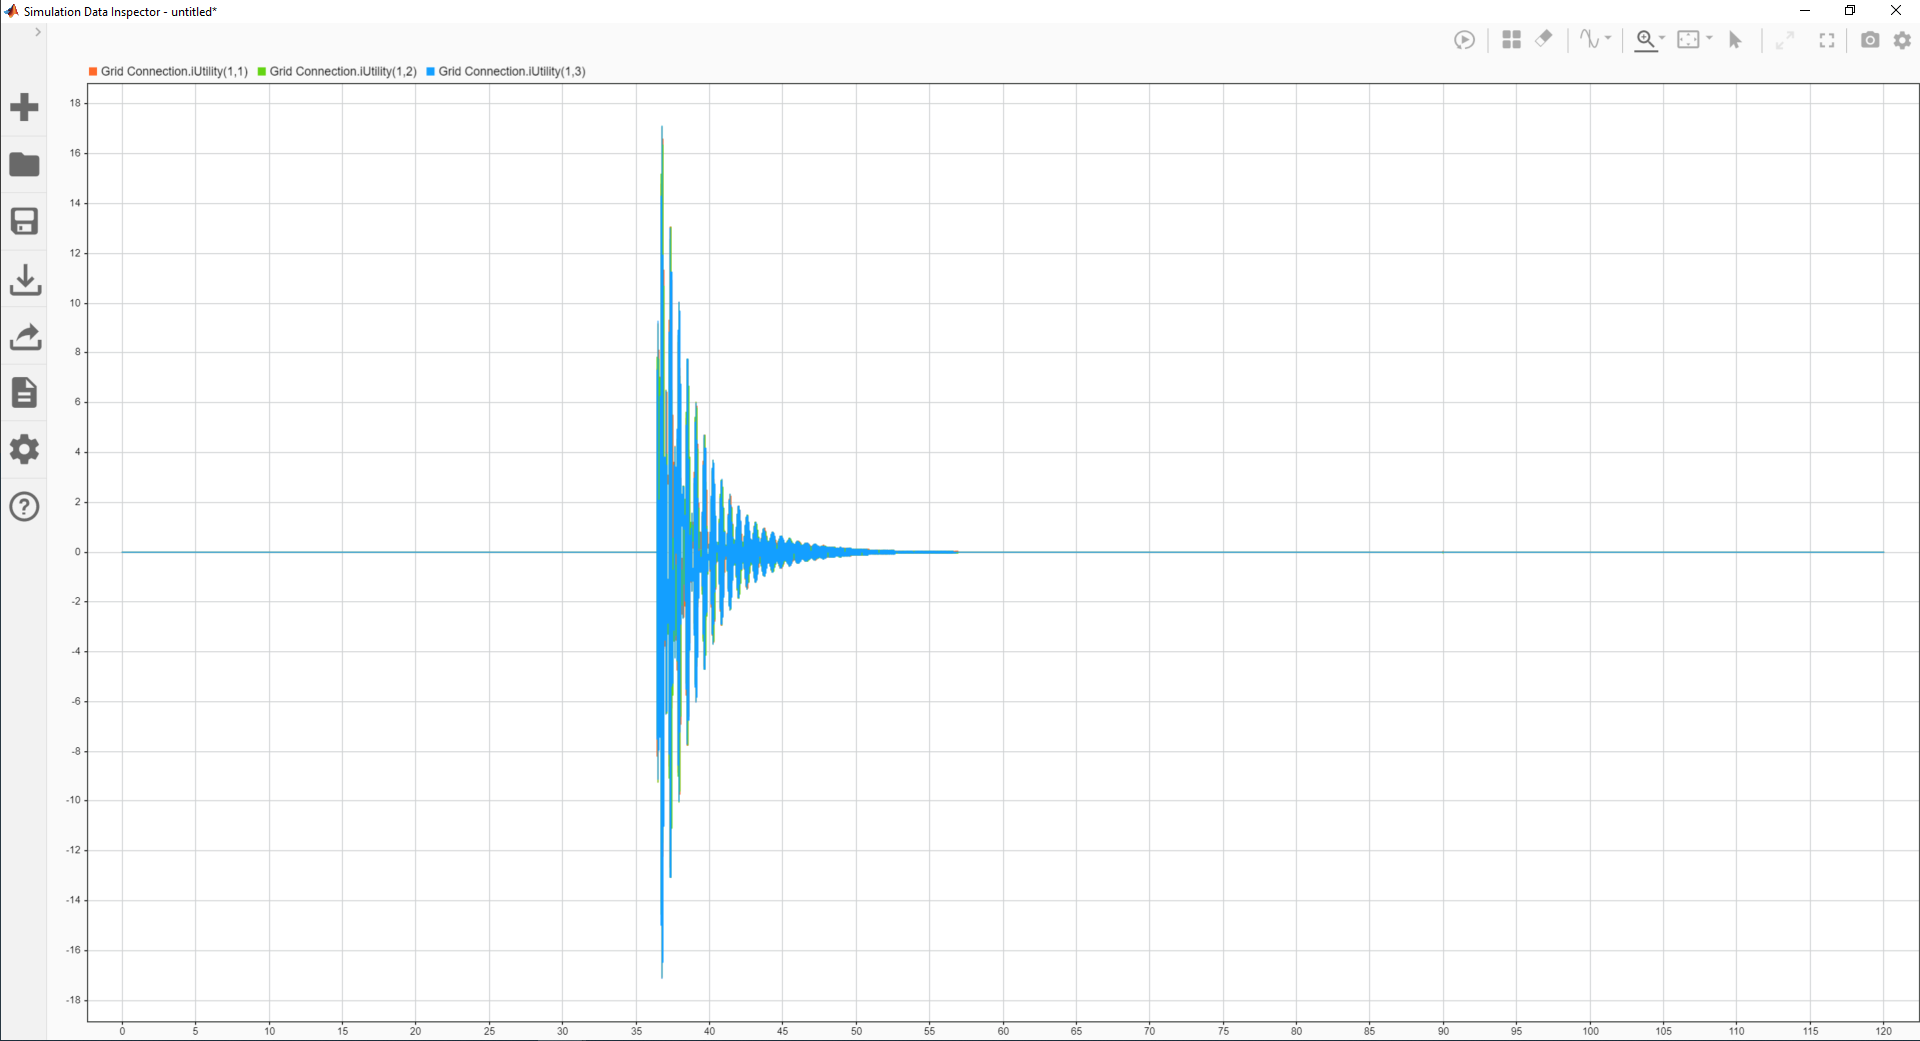

Double click on the grid synchronization MATLAB function and on line 31 change the phase tolerance from 1e-2 to 1e2. We are basically instructing the algorithm to close the breaker as soon as the frequencies are within tolerance.

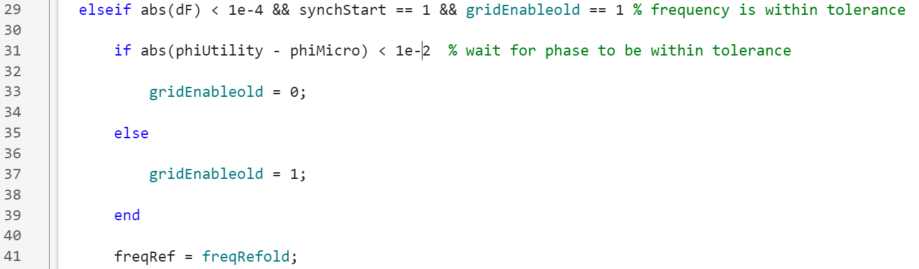

Now look at the current flowing through the PCC, shown below. Peak current in this case is around 2500 A, so we can see that waiting for the phases to overlap before we connect significantly reduces the PCC current when the breaker is closed. Large current flows like this can play havoc with the system. Take a look at the AC generator powers below and you can see that an unsynchronized connection has cause the generators to exceed their rating and has introduced unpleasant oscillations. 

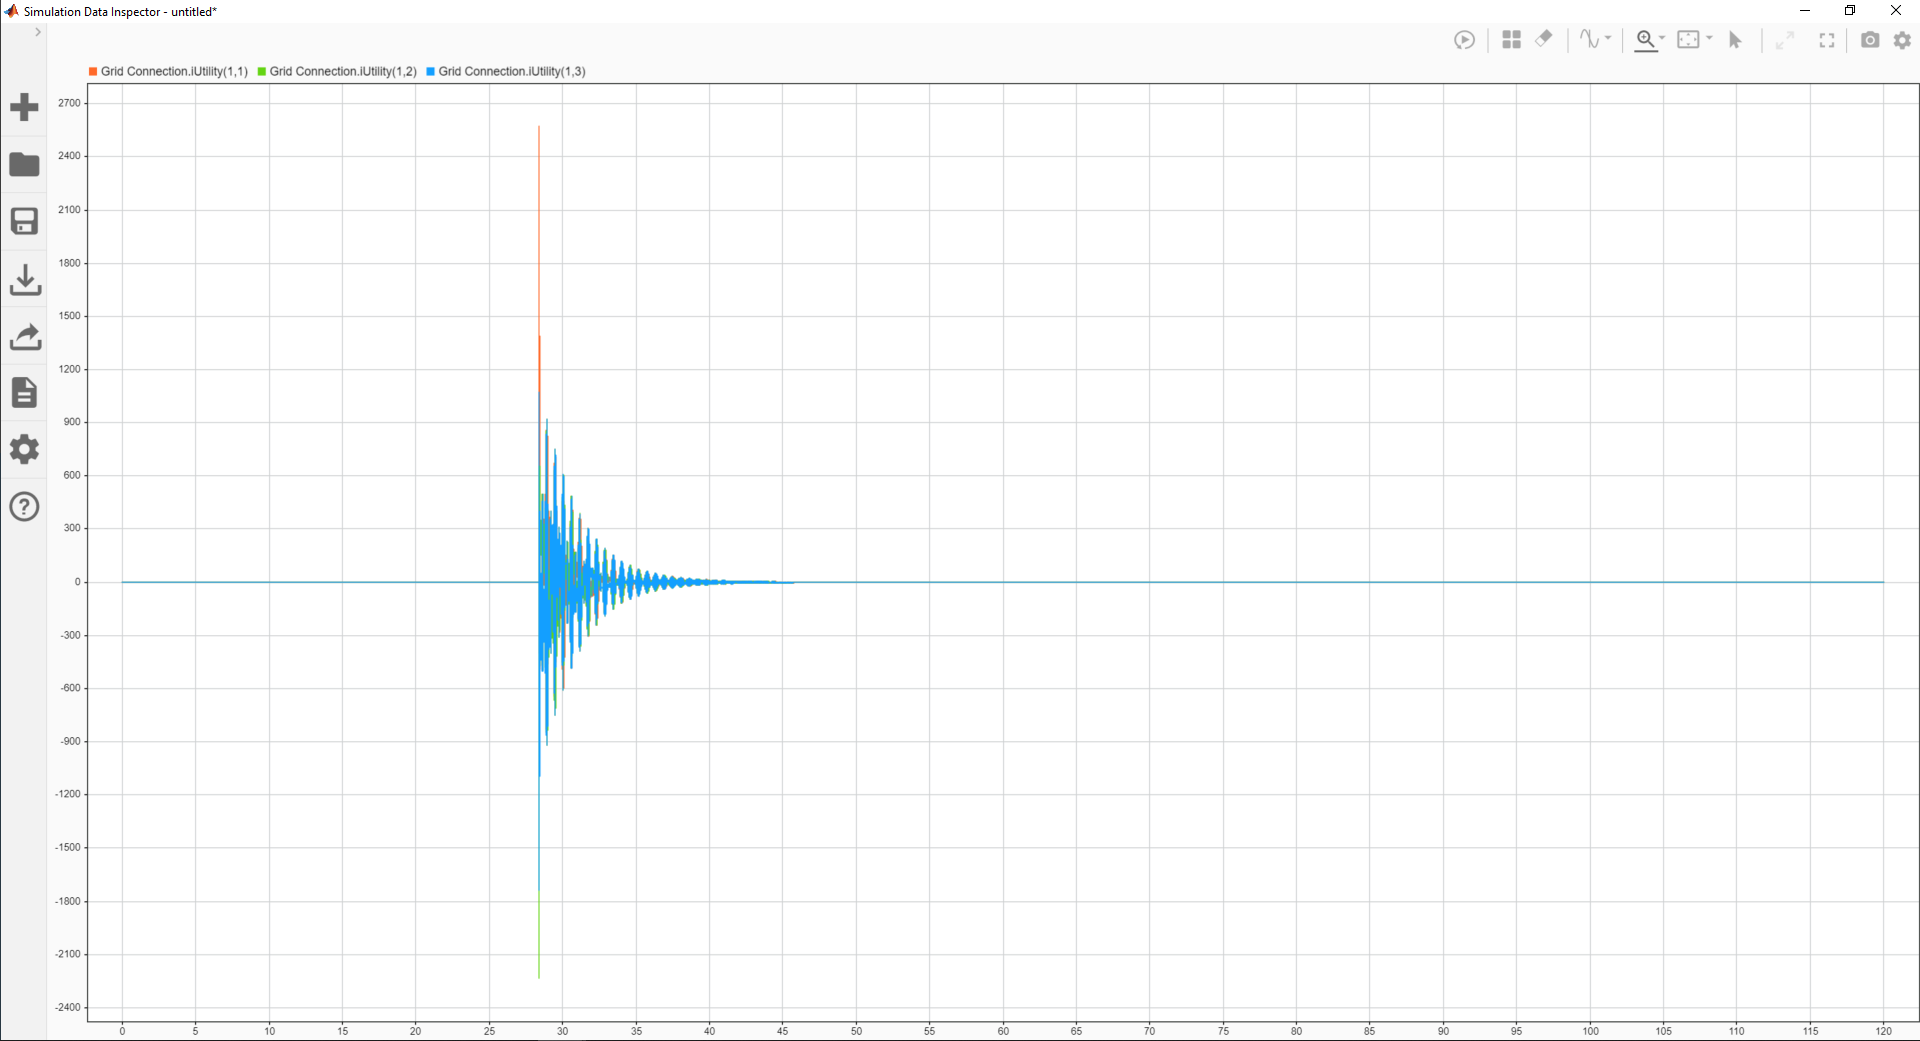

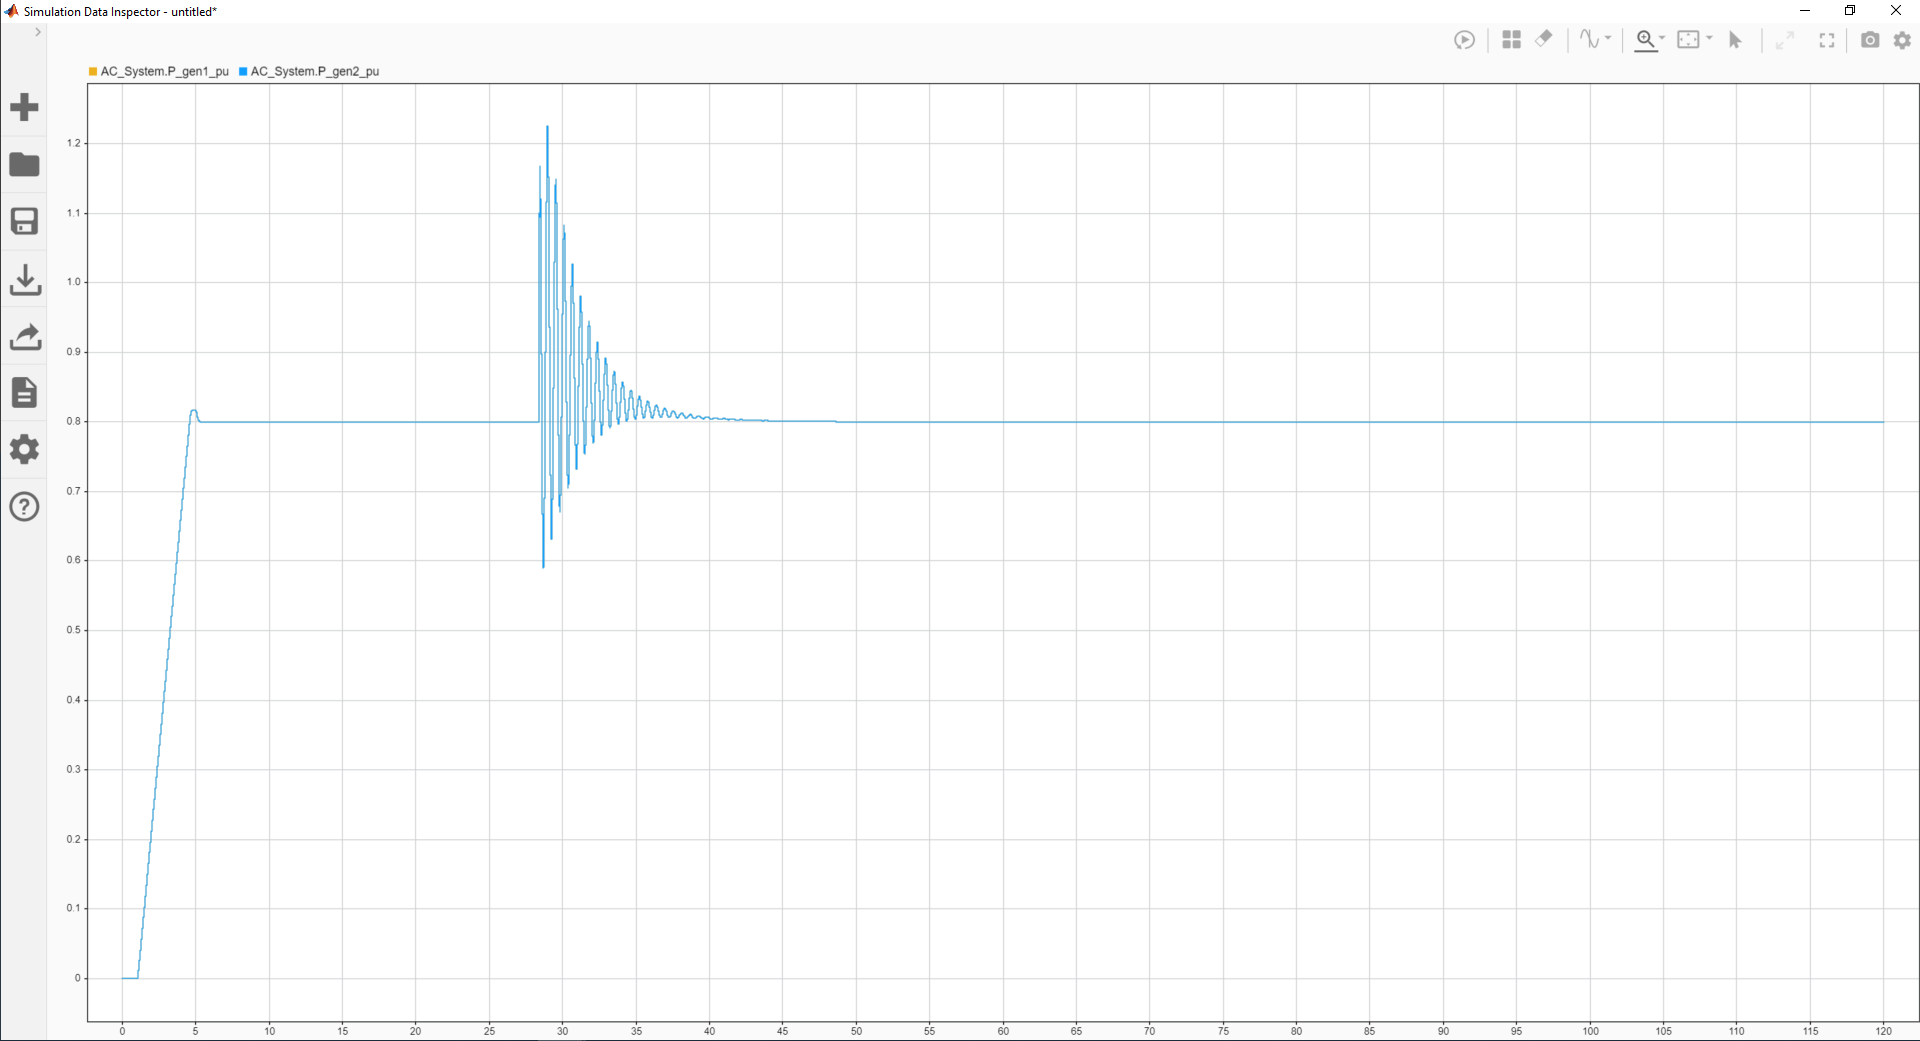 

You may also want to revisit the AC generator power for the correct synchronization scenario, which we show below for convenience. Notice that there is barely a blip on AC generator power when we synchronize correctly.

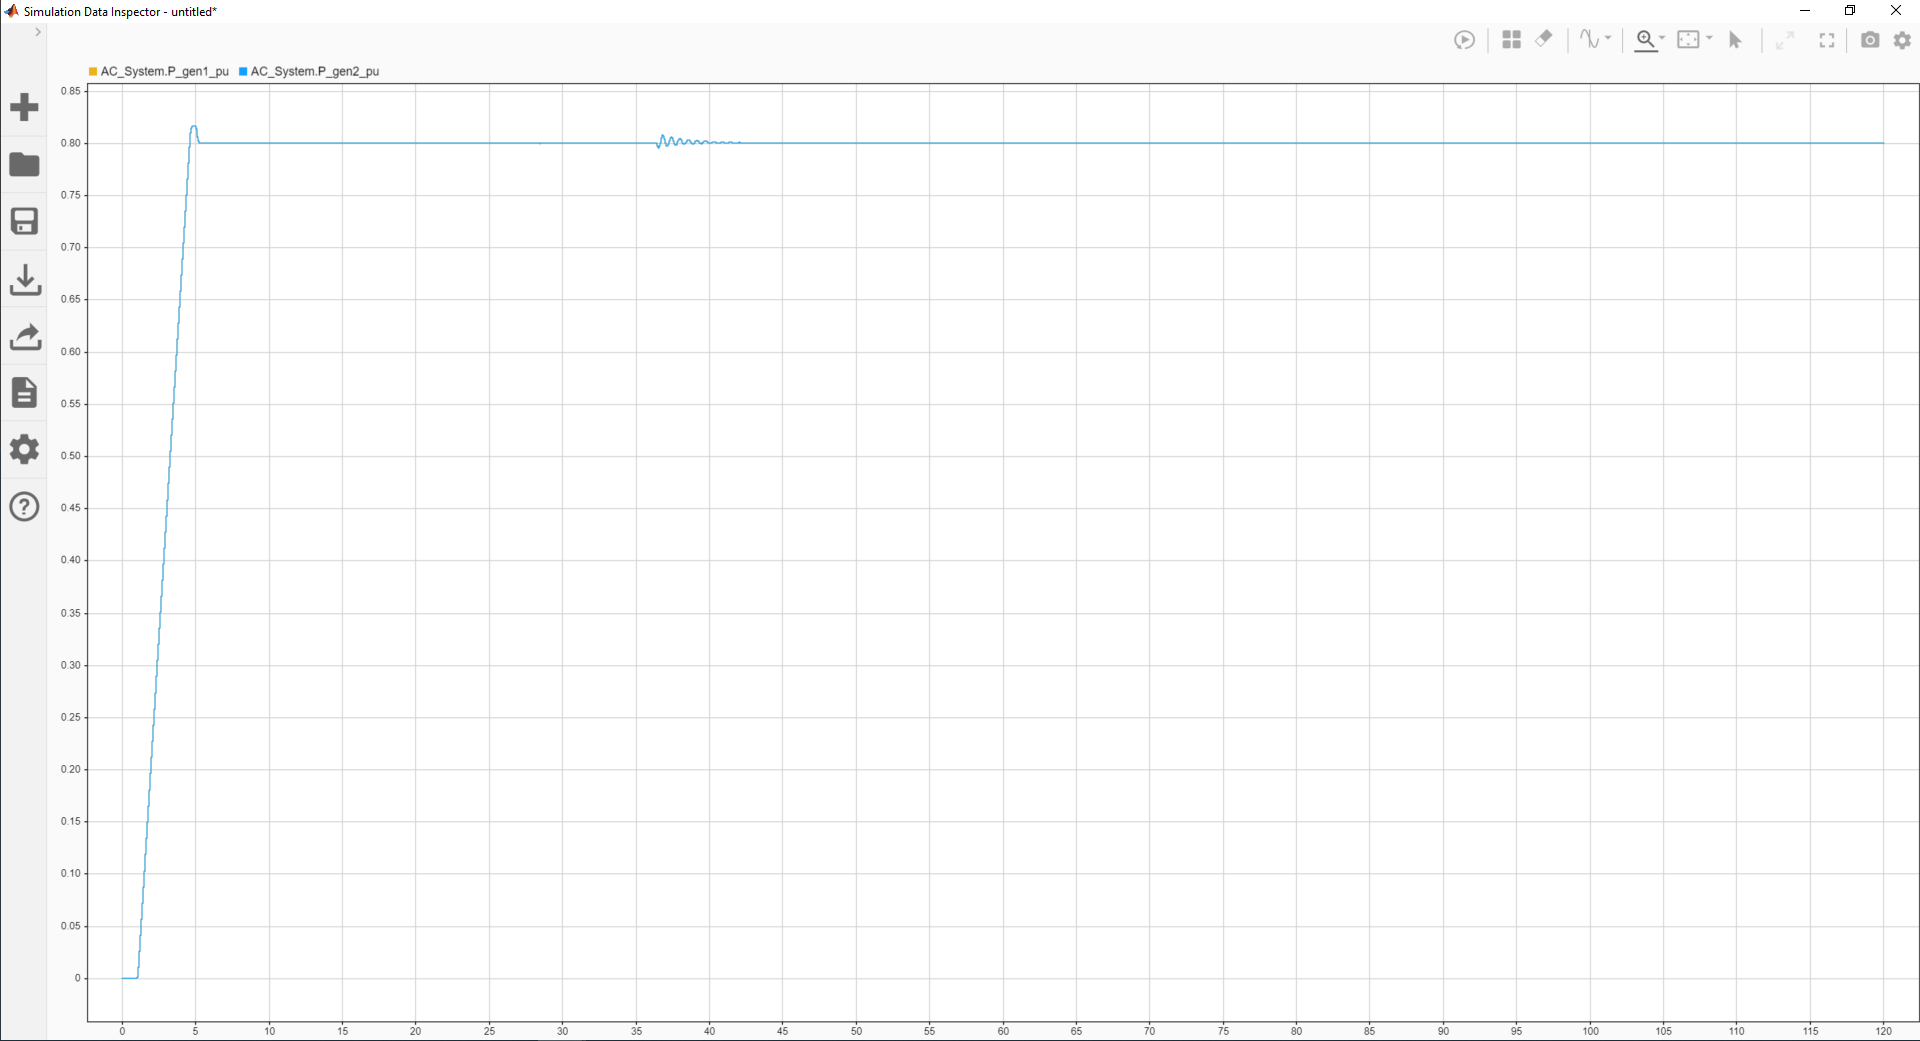

## Grid Forming / Grid Following

In our example, we are going to look specifically at changing the AC generator control systems from grid forming to grid following, depending on the connection status with the utility grid.

When the microgrid is in islanded mode, i.e. disconnected from the utility grid, then the AC generators are operating in grid forming mode, meaning that they are directly responsible for controlling voltage and frequency. Because we have two AC generators, we operate under voltage droop and frequency droop to give us the added advantage of providing precise active and reactive power sharing.

When the microgrid is in grid-connected mode, then the utility grid acts as the grid forming system as it is the utility grid that determines voltage and frequency. In this mode, we switch the AC generators to grid following mode, where instead of directly controlling voltage and frequency. we instead directly control active and reactive power.

The first step is to send a signal to the AC generators to inform them wthere they are in grid forming or grid following mode. Double click on the Grid Forming/Following subsystem. This simply looks at the gridEnable signal, and if the utility grid is connected then genMode is set for grid following (set to 1), and if the utility grid is disconnected then genMode is set for grid forming (set to 0).

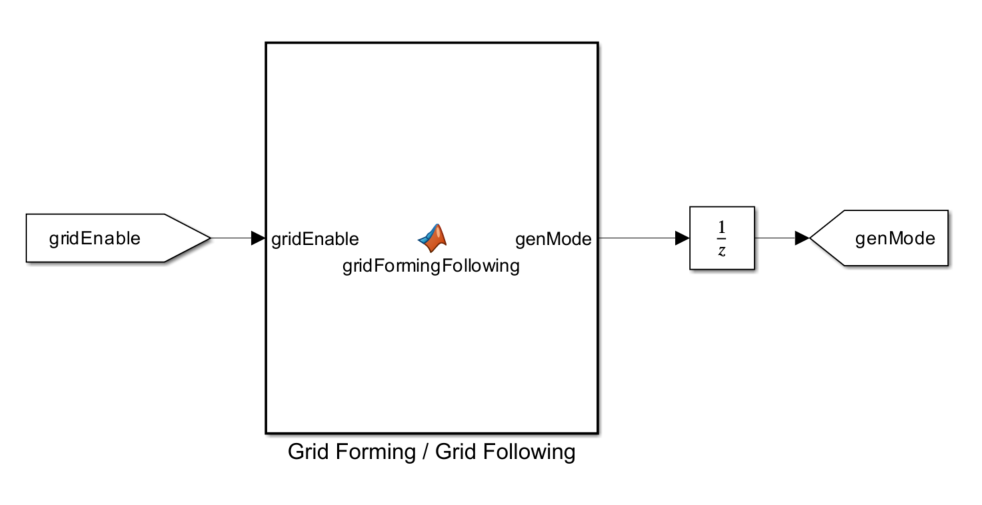

We'll now look at the generator control architectures. Shown below is the frequency and active power control system of generator 1. If we are grid forming then the Ferror path is enabled, which is standard frequency droop. If we are grid following then the Perror path is enabled, which is active power control.

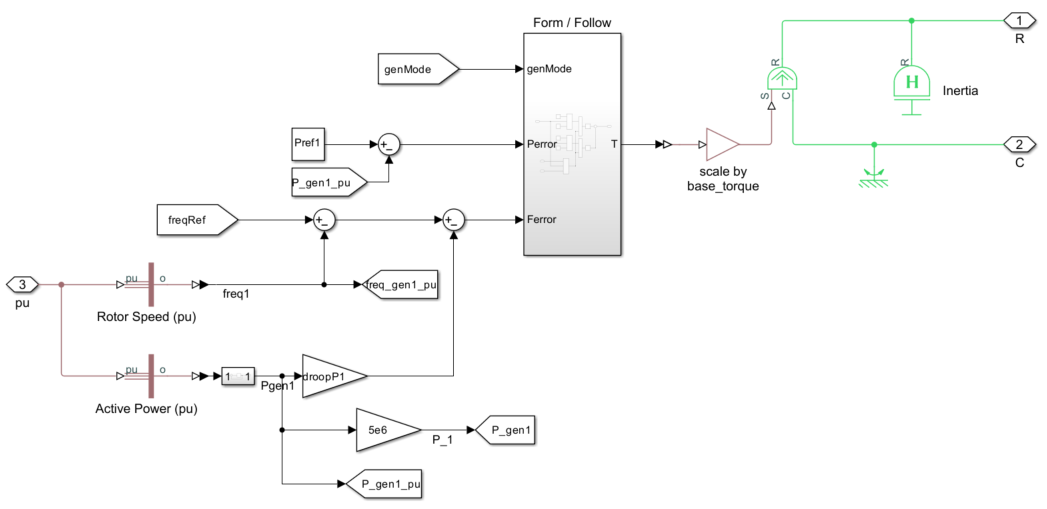

Shown below is the voltage and reactive power control system of generator 1. If we are grid forming then the Verror path is enabled, which is standard voltage droop. If we are grid following then the Qerror path is enabled, which is reactive power control.

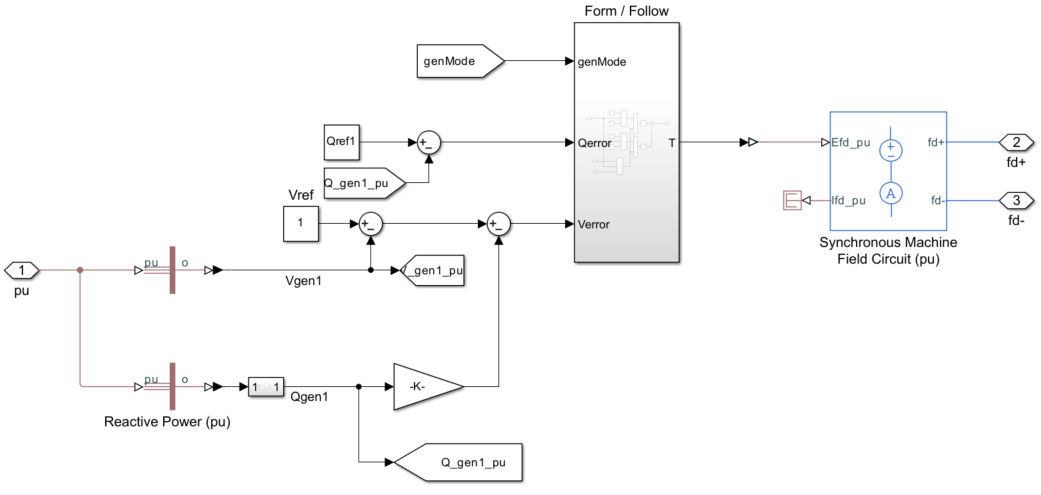

If you double click on the Form/Follow subsystem you will see that we not only switch between error signals but also switch between different proportional + integral control gains depending on what control mode we are in.

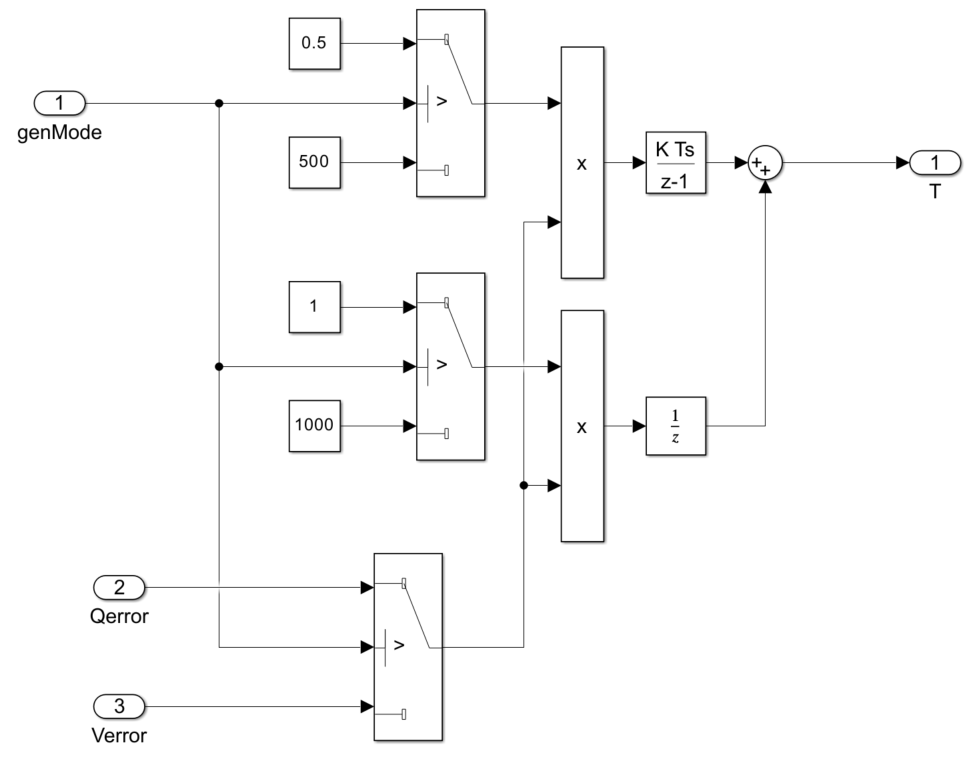

Our system is currently set up to send a grid synchronization signal at 27 seconds to begin a synchronization sequence, and then at 90 seconds a signal is sent to disconnect the microgrid from the utility grid. In order to see specific changes in grid forming and grid following control activity, we will make some changes to the active and reactive power reference commands as follows,

Pref1 = 0.4;
Pref2 = 0.6;
Qref1 = -0.3;
Qref2 = 0.1;

Now run the simulation. Next look at the active and reactive powers of the AC generators. You can see that the microgrid connects to the utility grid at around 38 seconds and then the grid following active and reactive power references come into play. At 90 seconds, the microgrid is disconnected from the utility grid and the AC generators go back to grid forming mode.

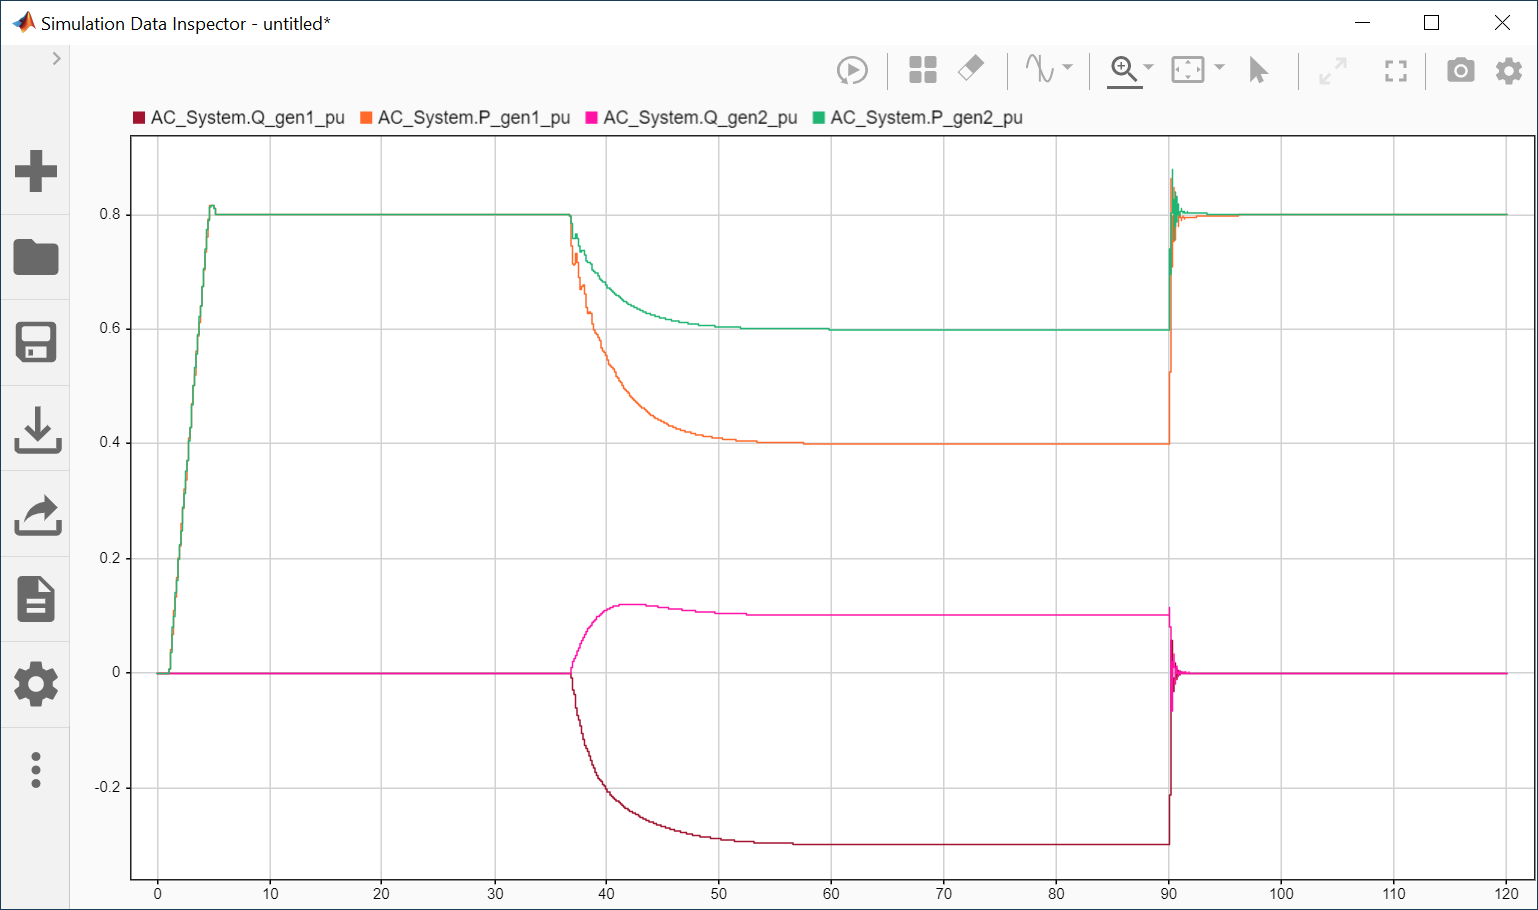 

The current flow through the PCC is shown below. Note that the transient on connection is minimal, and that we are supplying power from the utility grid because the power references we have during grid following do not match our microgrid load.

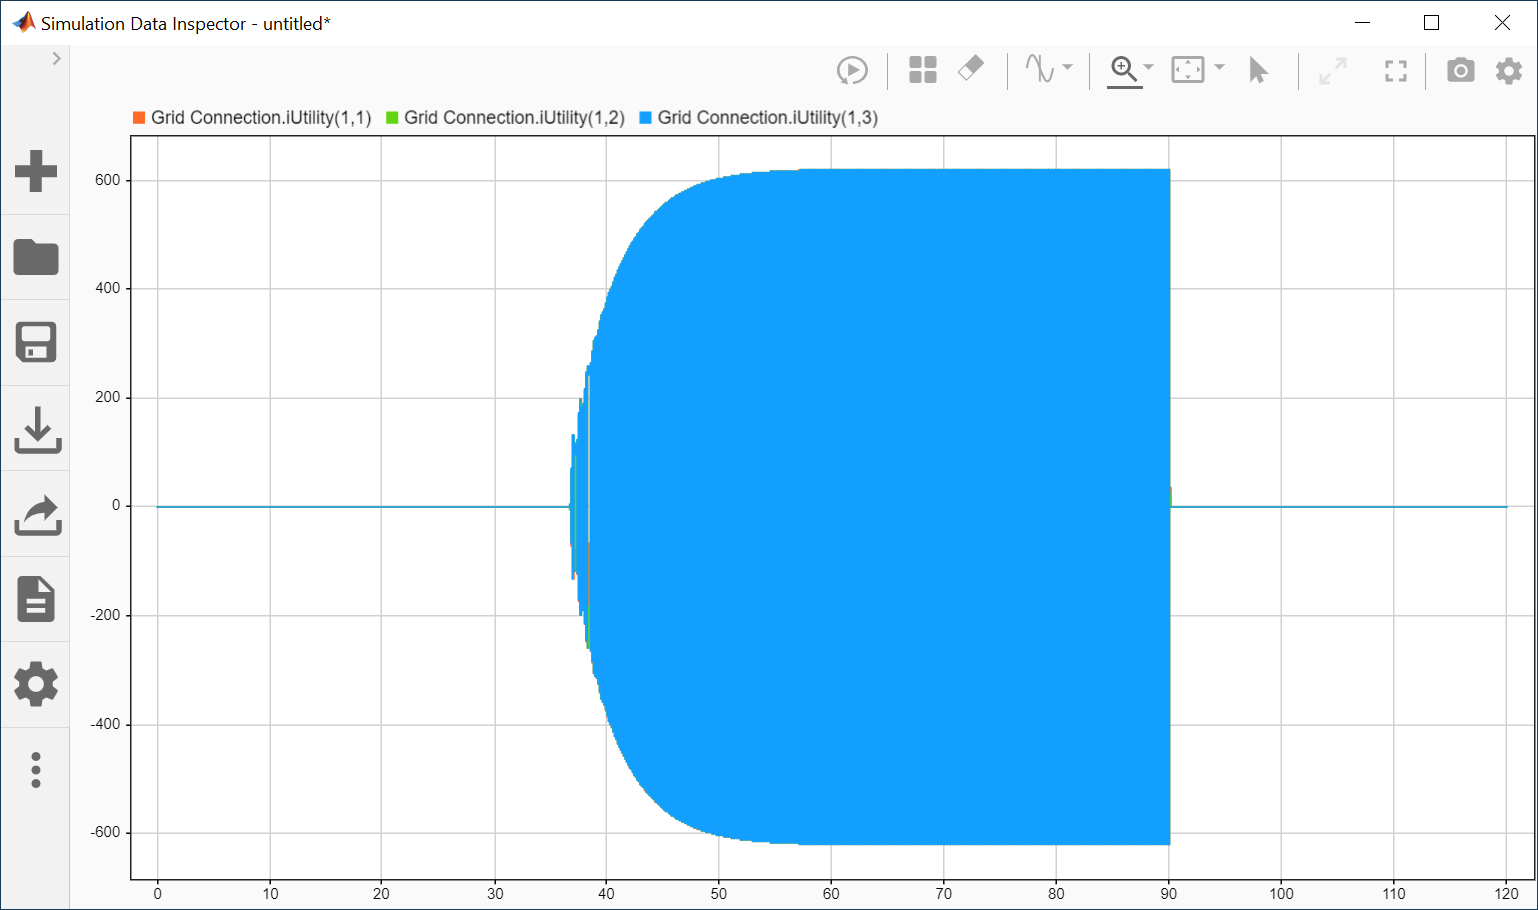

The utility grid active and reactive power is shown below.

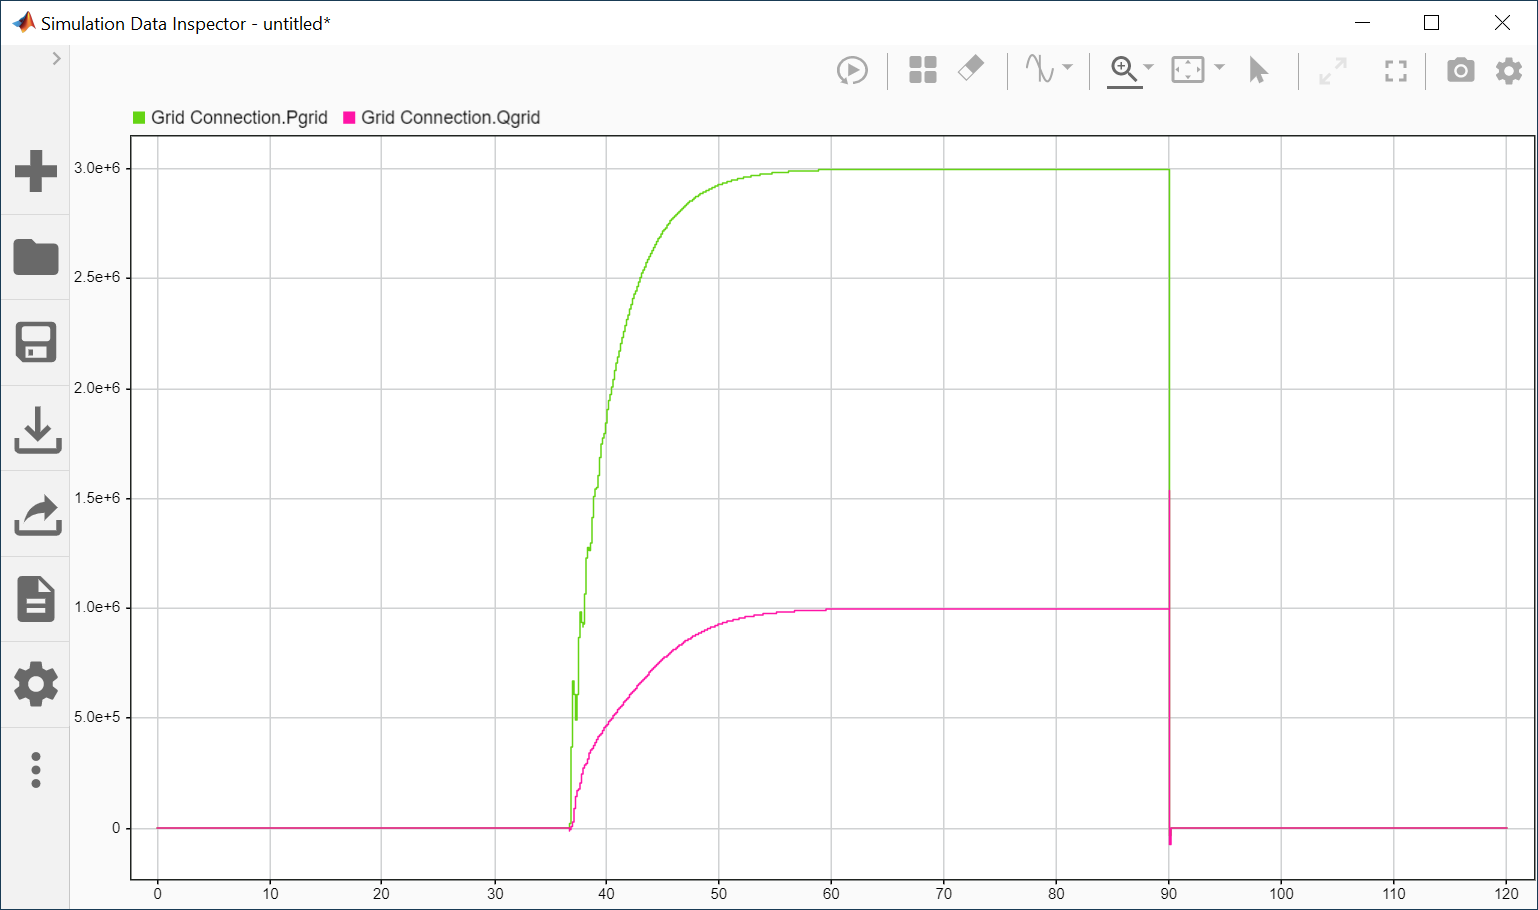

## Generator and Load Curtailment

Next, we will look at curtailing generation and load. Curtailment means we are going to reduce load demand and generator output. Specifically, we will curtail solar power and AC active power load. Double click on the Curtailment subsystem. You will see in this case we are simply commanding a curtialment at a specific time. 

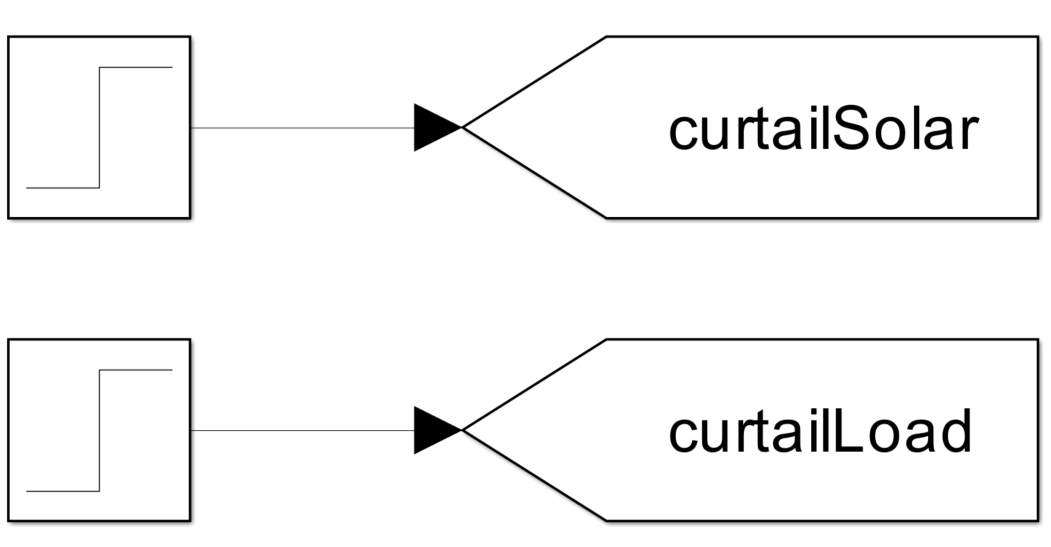

Set the following curtailment times,

timeSolarCurtail = 60;
timeACLoadCurtail = 70;

Double click on the PV Converter subsystem. You can see that during normal operation the PV system operates in maximum power point tracking (MPPT) mode, When a curtailment signal is received, the PV system switches to power reference control and the power is curtailed to a given power reference.

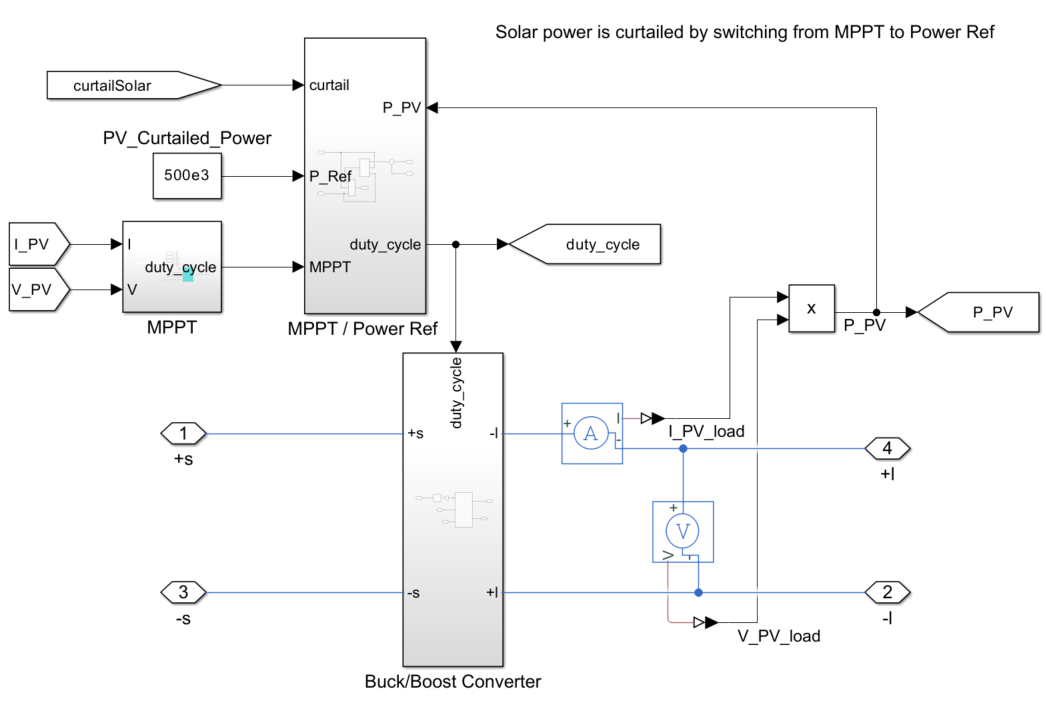

Double click on the Active Power Load subsystem and then double clock on the Curtail subsystem.

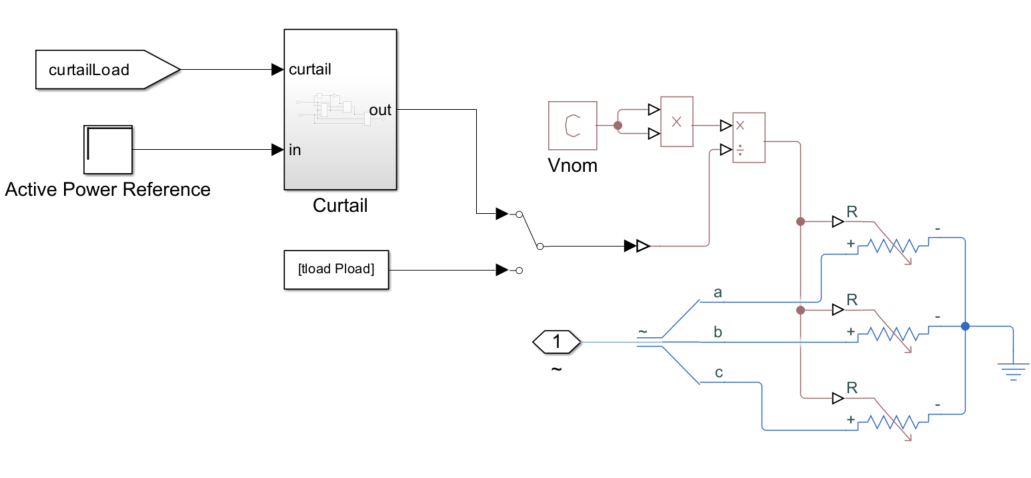

When the curtail signal is sent to the Active Power Load, the load setpoint simply ramps down to a curtailment value, which is set as a lower saturtation limit in the Discrete-Time Integrator block.

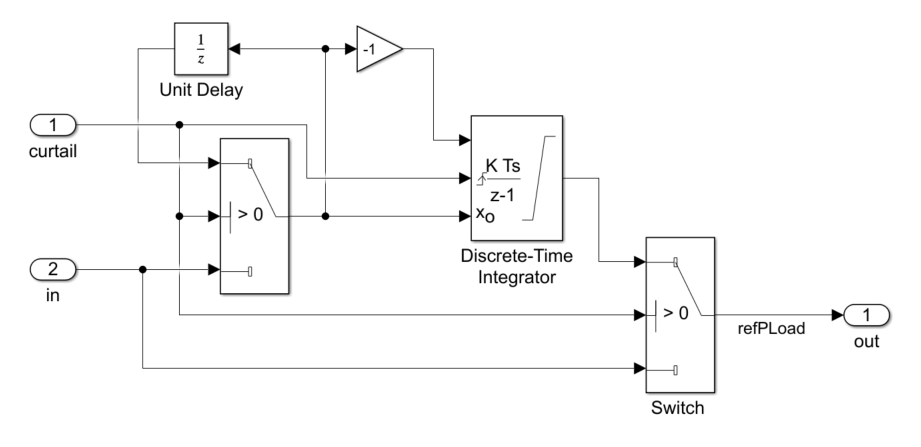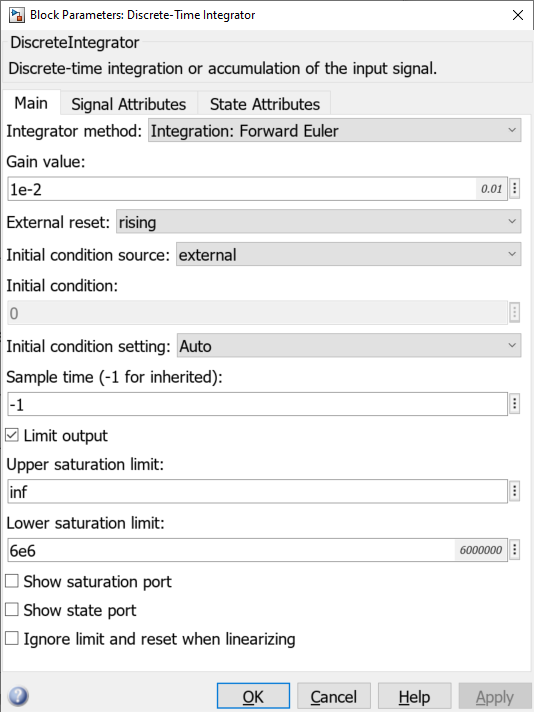

Now run the simulation. AC load power and PV power are shown below. Note that AC load power ramps down to its curtailment value and that PV power drops to its curtailment value based on the power reference control system.

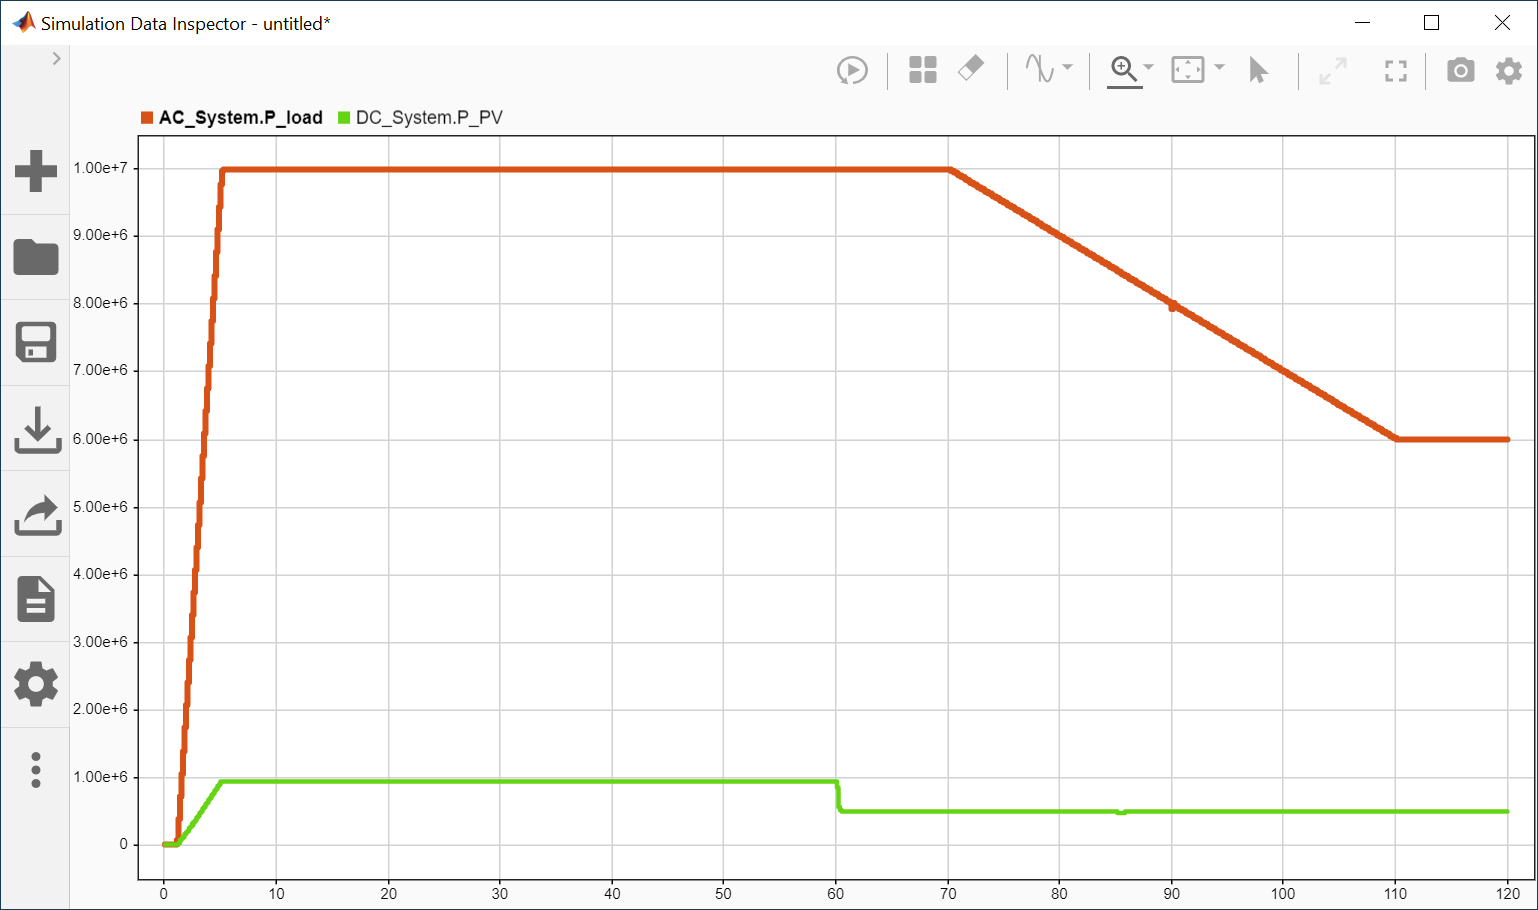

Utility grid power is shown below. Note that utility grid active power starts ramping down after 80 seconds as the active power load is curtailed.

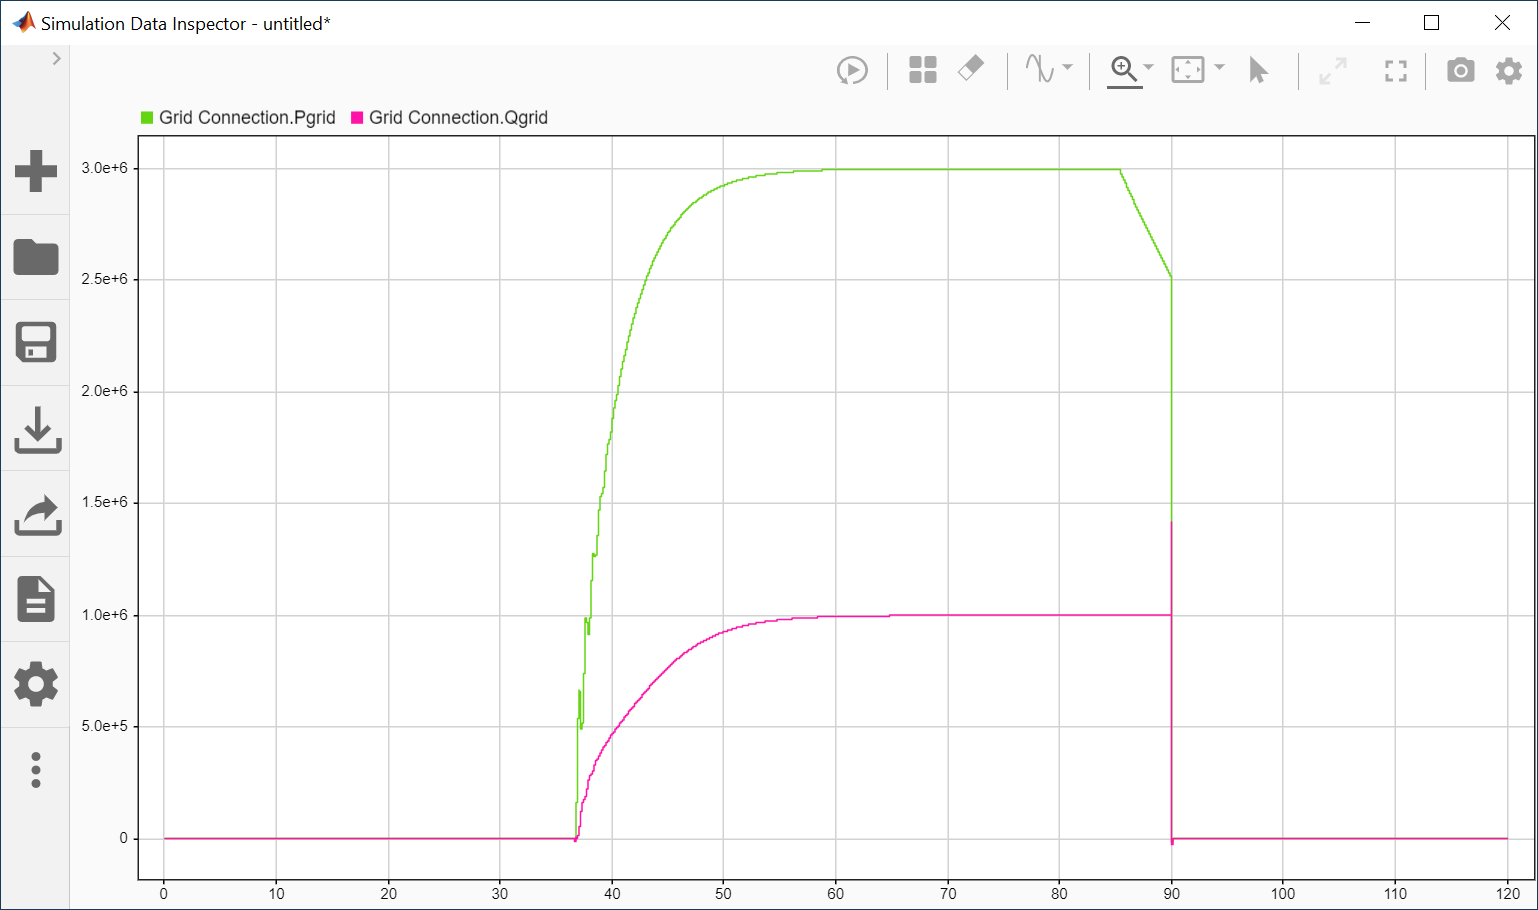

#### AC/DC Power Transfer

We covered AC/DC Power Transfer in more detail in Session 2. Please refer to Session 2 - part 7 for more detail.

**END OF SECTION**